clearvars; close all; clc

% 获取目标导联的索引
channame_full = ["Fp1","Fp2","Fz","F3","F4","F7","F8","FC1","FC2","FC5","FC6","Cz","C3","C4","T7","T8","CP1","CP2","CP5","CP6","Pz","P3","P4","P7","P8","Oz","O1","O2"];
channame_target1 = ["Fp1","Fp2","Fz"];
channame_target2 = ["C3","C4","CP1","CP2","CP5","CP6","Pz","P3","P4","P7","P8","Oz","O1","O2"];
chan_tar_ind=zeros([1,length(channame_target1)]);
for i=1:length(channame_target1)
    chan_tar_ind(i)=find(channame_full==channame_target1(i));
end
% 频段
f_low=2;f_high = 15;
% 时间位移最大量
T=10;

% 导入编码序列
load('idx_files/idx_coo_state1.mat');
load('idx_files/idx_coo_state2.mat');
load('idx_files/idx_coo_state1_inv.mat');
load('idx_files/idx_coo_state2_inv.mat');

statenum = "state1";
subclass = "adult";% adult or child
if statenum == "state1"
    idx_coo_sub=idx_coo_state1;
elseif statenum == "state2"
    idx_coo_sub=idx_coo_state2;
elseif statenum == "state1inv"
    idx_coo_sub=idx_coo_state1_inv;
elseif statenum == "state2inv"
    idx_coo_sub=idx_coo_state2_inv;
end

% 导入EEG数据
path_data = 'D:\个人work\研究生\课题\亲子互动-频段切换\Code&Data\eegdata_dynamic';
addpath 'D:\个人work\研究生\课题\亲子互动-频段切换\Code&Data\eegdata_dynamic'
Files = dir(fullfile([path_data,'\*.mat']));
LengthFiles = length(Files);

% 所有被试的相关结果汇总
sperm_all = zeros([f_high-f_low+1,2*T+1,LengthFiles]);
ran_times=1000;
sperm_phaseran_all = zeros([f_high-f_low+1,2*T+1,ran_times,LengthFiles]);

t=1;
for i=1:LengthFiles
    file_name=Files(i).name;
    load(file_name);
    
    % 导入EEG序列   
    if subclass == "adult"
        eeg_sub = eeg_a;
    elseif subclass == "child"
        eeg_sub = eeg_c;
    end
    
    num_tangram=length(eeg_sub);
    sperm_epo = zeros([f_high-f_low+1,2*T+1,num_tangram]);
   
    for nt=1:num_tangram
        % 将EEG时间序列分段，采用去尾法删除多余
        sel_eeg=eeg_sub{nt,1};
        data_length=size(sel_eeg,2);
        if data_length>0
            step=100;
            window=1000;
            data_length=data_length-mod(data_length,step);
            num_trail=(data_length-window)/step+1;
        end
        % 计算每个时间段的各频段功率P_tar
        P_tar=zeros([f_high-f_low+1,num_trail]);
        for k=1:num_trail
           eeg_tar = sel_eeg(chan_tar_ind,((k-1)*step+1):((k-1)*step+window));
           eeg_tar_mean = mean(eeg_tar,1);
           P_tar_sing = get_power(eeg_tar_mean,1000,1000,f_low,f_high);
           P_tar(:,k) = P_tar_sing;
        end
    
        % 将各频段功率P_tar与编码序列idx_cor做相关
        idx_cor = idx_coo_sub(t:t+num_trail-1);
        sperm = zeros([f_high-f_low+1,2*T+1]);
        sperm_phaseran = zeros([f_high-f_low+1,2*T+1,ran_times]);
        sperm_phaseran_epo = zeros([f_high-f_low+1,2*T+1,ran_times,num_tangram]);        
        
        for f=1:f_high-f_low+1
            P_tar_lag=expand_lag(P_tar(f,:),T,num_trail);
            sperm(f,:) = corr(P_tar_lag,idx_cor);
            % 保持功率信息打乱信号           
            P_phase_ran = phaseran(P_tar(f,:)',ran_times);
            num_trail_rv = size(P_phase_ran,1);
            P_phaseran_rs = reshape(P_phase_ran,[num_trail_rv,ran_times]);
            for sample=1:1000
                P_phaseran_lag=expand_lag(P_phaseran_rs(:,sample)',T,num_trail_rv);
                sperm_phaseran(f,:,sample) = corr(P_phaseran_lag,idx_cor(1:num_trail_rv));
            end
        end
        
        sperm_epo(:,:,nt) = sperm;
        sperm_mean = mean(sperm_epo,3);
        sperm_phaseran_epo(:,:,:,nt) = sperm_phaseran;
        sperm_phaseran_mean = mean(sperm_phaseran_epo,4);
        t=t+num_trail;
        %h_ind(i) = draw_heatmap(sperm_mean,T,f_low,f_high,[statenum,subclass,num2str(i)]);
    end
    
    sperm_all(:,:,i) = sperm_mean;
    sperm_phaseran_all(:,:,:,i) = sperm_phaseran_mean;
end

sperm_all_mean = mean(sperm_all,3);
sperm_phaseran_all_mean = mean(sperm_phaseran_all,4);

% 保存文件
% 绘制时频图
fn_sav = strcat("tf_results_fp/tf_phaseran_",subclass,"_",statenum,".mat");
save(fn_sav,"sperm_phaseran_all_mean")

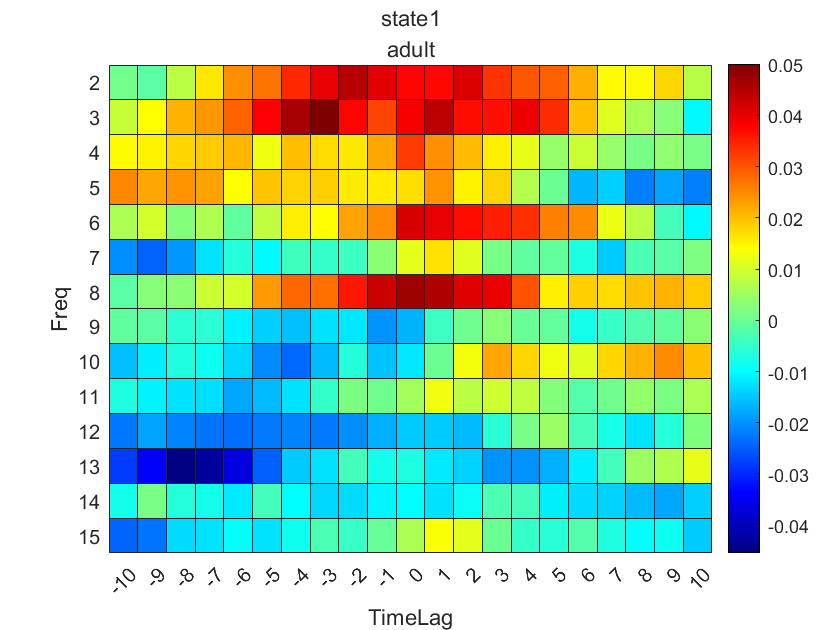

fn_sav = strcat("tf_results_fp/tf_",subclass,"_",statenum,".mat");
save(fn_sav,"sperm_all_mean")
h = draw_heatmap(sperm_all_mean,T,f_low,f_high,[statenum,subclass],-0.06,0.06);

% num = 3;
% h3 = draw_heatmap(sperm_all(:,:,num),T,f_low,f_high,["subject",num2str(num)]);
% num = 6;
% h6 = draw_heatmap(sperm_all(:,:,num),T,f_low,f_high,["subject",num2str(num)]);
% num = 9;
% h9 = draw_heatmap(sperm_all(:,:,num),T,f_low,f_high,["subject",num2str(num)]);
% num = 18;
% h18 = draw_heatmap(sperm_all(:,:,num),T,f_low,f_high,["subject",num2str(num)]);